## Rabi sequence calculation

The pulse sequence is (roughly): laser-delay-MW-delay-laser-delay-readout

Units: us (10^-6 s)

T_swp = 0.06    %10 ns

T_swp = 0.0600

T_pi = 0.1      %100 ns

T_pi = 0.1000

K0 = zeros(7,7);

beta = 0;
k0_r = 63;
k0_47 = 13;
k0_57 = 80;
k0_71 = 3.5;
k0_72 = 2.2;
K0(1,4) = beta*k0_r;
K0(2,5) = beta*k0_r;
K0(3,6) = beta*k0_r;
K0(4,1) = k0_r;
K0(5,2) = k0_r;
K0(6,3) = k0_r;
K0(4,7) = k0_47;
K0(5,7) = k0_57;
K0(6,7) = k0_57;
K0(7,1) = k0_71;
K0(7,2) = k0_72;
K0(7,3) = k0_72;

K0_off = K0   %K matrix when laser is off (/beta = 0)

K0_off =          0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
   63.0000         0         0         0         0         0   13.0000
         0   63.0000         0         0         0         0   80.0000
         0         0   63.0000         0         0         0   80.0000
    3.5000    2.2000    2.2000         0         0         0         0



K0 = zeros(7,7);
 
beta = 0.3;
k0_r = 63;
k0_47 = 13;
k0_57 = 80;
k0_71 = 3.5;
k0_72 = 2.2;
K0(1,4) = beta*k0_r;
K0(2,5) = beta*k0_r;
K0(3,6) = beta*k0_r;
K0(4,1) = k0_r;
K0(5,2) = k0_r;
K0(6,3) = k0_r;
K0(4,7) = k0_47;
K0(5,7) = k0_57;
K0(6,7) = k0_57;
K0(7,1) = k0_71;
K0(7,2) = k0_72;
K0(7,3) = k0_72;

K0_on = K0       %K matrix when laser is on (/beta = 0.3)

K0_on =          0         0         0   18.9000         0         0         0
         0         0         0         0   18.9000         0         0
         0         0         0         0         0   18.9000         0
   63.0000         0         0         0         0         0   13.0000
         0   63.0000         0         0         0         0   80.0000
         0         0   63.0000         0         0         0   80.0000
    3.5000    2.2000    2.2000         0         0         0         0


### t = 0 to t = t_1 = 5.18 us

Laser on, /beta = 0.3

K = K0_on;
ode1 = @(t, y) K(1,1)*y(1) - K(1,1)*y(1)...
             + K(2,1)*y(2) - K(1,2)*y(1)...
             + K(3,1)*y(3) - K(1,3)*y(1)...
             + K(4,1)*y(4) - K(1,4)*y(1)...
             + K(5,1)*y(5) - K(1,5)*y(1)...
             + K(6,1)*y(6) - K(1,6)*y(1)...
             + K(7,1)*y(7) - K(1,7)*y(1);
        
ode2 = @(t, y) K(1,2)*y(1) - K(2,1)*y(2)...
             + K(2,2)*y(2) - K(2,2)*y(2)...
             + K(3,2)*y(3) - K(2,3)*y(2)...
             + K(4,2)*y(4) - K(2,4)*y(2)...
             + K(5,2)*y(5) - K(2,5)*y(2)...
             + K(6,2)*y(6) - K(2,6)*y(2)...
             + K(7,2)*y(7) - K(2,7)*y(2);

ode3 = @(t, y) K(1,3)*y(1) - K(3,1)*y(3)...
             + K(2,3)*y(2) - K(3,2)*y(3)...
             + K(3,3)*y(3) - K(3,3)*y(3)...
             + K(4,3)*y(4) - K(3,4)*y(3)...
             + K(5,3)*y(5) - K(3,5)*y(3)...
             + K(6,3)*y(6) - K(3,6)*y(3)...
             + K(7,3)*y(7) - K(3,7)*y(3);
        
ode4 = @(t, y) K(1,4)*y(1) - K(4,1)*y(4)...
             + K(2,4)*y(2) - K(4,2)*y(4)...
             + K(3,4)*y(3) - K(4,3)*y(4)...
             + K(4,4)*y(4) - K(4,4)*y(4)...
             + K(5,4)*y(5) - K(4,5)*y(4)...
             + K(6,4)*y(6) - K(4,6)*y(4)...
             + K(7,4)*y(7) - K(4,7)*y(4);
        
ode5 = @(t, y) K(1,5)*y(1) - K(5,1)*y(5)...
             + K(2,5)*y(2) - K(5,2)*y(5)...
             + K(3,5)*y(3) - K(5,3)*y(5)...
             + K(4,5)*y(4) - K(5,4)*y(5)...
             + K(5,5)*y(5) - K(5,5)*y(5)...
             + K(6,5)*y(6) - K(5,6)*y(5)...
             + K(7,5)*y(7) - K(5,7)*y(5);

ode6 = @(t, y) K(1,6)*y(1) - K(6,1)*y(6)...
             + K(2,6)*y(2) - K(6,2)*y(6)...
             + K(3,6)*y(3) - K(6,3)*y(6)...
             + K(4,6)*y(4) - K(6,4)*y(6)...
             + K(5,6)*y(5) - K(6,5)*y(6)...
             + K(6,6)*y(6) - K(6,6)*y(6)...
             + K(7,6)*y(7) - K(6,7)*y(6);
        
ode7 = @(t, y) K(1,7)*y(1) - K(7,1)*y(7)...
             + K(2,7)*y(2) - K(7,2)*y(7)...
             + K(3,7)*y(3) - K(7,3)*y(7)...
             + K(4,7)*y(4) - K(7,4)*y(7)...
             + K(5,7)*y(5) - K(7,5)*y(7)...
             + K(6,7)*y(6) - K(7,6)*y(7)...
             + K(7,7)*y(7) - K(7,7)*y(7);

odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

init = [1/3; 1/3; 1/3; 0; 0; 0; 0];
[t1, n_res_laser_1] = ode45(odes, [0:1e-3:5180e-3], init);

### t_1 = 5.18 us to t_2 = 11.192 us

Delay, laser off, /beta = 0

Get initial values from previous section

init = zeros(7,1);
for i = 1:7
    init_temp = n_res_laser_1(:, i);
    init(i, 1) = init_temp(end);
end

K = K0_off;
ode1 = @(t, y) K(1,1)*y(1) - K(1,1)*y(1)...
             + K(2,1)*y(2) - K(1,2)*y(1)...
             + K(3,1)*y(3) - K(1,3)*y(1)...
             + K(4,1)*y(4) - K(1,4)*y(1)...
             + K(5,1)*y(5) - K(1,5)*y(1)...
             + K(6,1)*y(6) - K(1,6)*y(1)...
             + K(7,1)*y(7) - K(1,7)*y(1);
        
ode2 = @(t, y) K(1,2)*y(1) - K(2,1)*y(2)...
             + K(2,2)*y(2) - K(2,2)*y(2)...
             + K(3,2)*y(3) - K(2,3)*y(2)...
             + K(4,2)*y(4) - K(2,4)*y(2)...
             + K(5,2)*y(5) - K(2,5)*y(2)...
             + K(6,2)*y(6) - K(2,6)*y(2)...
             + K(7,2)*y(7) - K(2,7)*y(2);

ode3 = @(t, y) K(1,3)*y(1) - K(3,1)*y(3)...
             + K(2,3)*y(2) - K(3,2)*y(3)...
             + K(3,3)*y(3) - K(3,3)*y(3)...
             + K(4,3)*y(4) - K(3,4)*y(3)...
             + K(5,3)*y(5) - K(3,5)*y(3)...
             + K(6,3)*y(6) - K(3,6)*y(3)...
             + K(7,3)*y(7) - K(3,7)*y(3);
        
ode4 = @(t, y) K(1,4)*y(1) - K(4,1)*y(4)...
             + K(2,4)*y(2) - K(4,2)*y(4)...
             + K(3,4)*y(3) - K(4,3)*y(4)...
             + K(4,4)*y(4) - K(4,4)*y(4)...
             + K(5,4)*y(5) - K(4,5)*y(4)...
             + K(6,4)*y(6) - K(4,6)*y(4)...
             + K(7,4)*y(7) - K(4,7)*y(4);
        
ode5 = @(t, y) K(1,5)*y(1) - K(5,1)*y(5)...
             + K(2,5)*y(2) - K(5,2)*y(5)...
             + K(3,5)*y(3) - K(5,3)*y(5)...
             + K(4,5)*y(4) - K(5,4)*y(5)...
             + K(5,5)*y(5) - K(5,5)*y(5)...
             + K(6,5)*y(6) - K(5,6)*y(5)...
             + K(7,5)*y(7) - K(5,7)*y(5);

ode6 = @(t, y) K(1,6)*y(1) - K(6,1)*y(6)...
             + K(2,6)*y(2) - K(6,2)*y(6)...
             + K(3,6)*y(3) - K(6,3)*y(6)...
             + K(4,6)*y(4) - K(6,4)*y(6)...
             + K(5,6)*y(5) - K(6,5)*y(6)...
             + K(6,6)*y(6) - K(6,6)*y(6)...
             + K(7,6)*y(7) - K(6,7)*y(6);
        
ode7 = @(t, y) K(1,7)*y(1) - K(7,1)*y(7)...
             + K(2,7)*y(2) - K(7,2)*y(7)...
             + K(3,7)*y(3) - K(7,3)*y(7)...
             + K(4,7)*y(4) - K(7,4)*y(7)...
             + K(5,7)*y(5) - K(7,5)*y(7)...
             + K(6,7)*y(6) - K(7,6)*y(7)...
             + K(7,7)*y(7) - K(7,7)*y(7);

odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

[t2, n_res_delay_1] = ode45(odes, [5.18 : 1e-3 : 11.192], init);
n_res_delay_1(1,:) = [];

### t_2 = 11.192 us to t_3 = T_swp + 11.192 us

MW turns on for T_swp. T_swp ranges from 0 to 100 ns (0.1 us)

init = zeros(7,1);
for i = 1:7
    init_temp = n_res_delay_1(:, i);
    init(i, 1) = init_temp(end);
end
% disp(init)

t3 = 0 : 1e-3 : T_swp;
length = size(t3);
n_1_0 = init(1,1)

n_1_0 = 0.6316

n_2_0 = init(2,1)

n_2_0 = 0.1842

n_1_tp = (n_1_0 - n_2_0)/2 * cos(pi * t3 / T_pi) + (n_1_0 + n_2_0)/2

n_1_tp =     0.6316    0.6314    0.6311    0.6306    0.6298    0.6288    0.6276    0.6262    0.6245    0.6227    0.6206    0.6183    0.6158    0.6132    0.6103    0.6072    0.6039    0.6004    0.5967    0.5929    0.5888    0.5846    0.5802    0.5757    0.5709    0.5660    0.5610    0.5558    0.5505    0.5450    0.5394    0.5336    0.5277    0.5217    0.5156    0.5094    0.5031    0.4967    0.4902    0.4837    0.4770    0.4703    0.4635    0.4567    0.4498    0.4429    0.4359    0.4289    0.4219    0.4149


n_2_tp = (n_1_0 + n_2_0) - n_1_tp

n_2_tp =     0.1842    0.1843    0.1847    0.1852    0.1860    0.1870    0.1882    0.1896    0.1912    0.1931    0.1952    0.1974    0.1999    0.2026    0.2055    0.2086    0.2119    0.2154    0.2190    0.2229    0.2269    0.2312    0.2356    0.2401    0.2448    0.2497    0.2548    0.2600    0.2653    0.2708    0.2764    0.2822    0.2880    0.2940    0.3001    0.3063    0.3127    0.3191    0.3256    0.3321    0.3388    0.3455    0.3523    0.3591    0.3660    0.3729    0.3799    0.3868    0.3938    0.4009



n_res_mw = zeros(length(2), 7);
n_res_mw(:, 1) = n_1_tp;
n_res_mw(:, 2) = n_2_tp;
for i = 3:7
    n_res_mw(:, i) = init(i, 1) .* ones(length(2), 1);
end
n_res_mw(1, :) = [];

### t_3 = T_swp + 11.192 us to t_4 = T_swp + 12.204 us

Delay, laser off, /beta = 0

Get the initial values

init = zeros(7,1);
for i = 1:7
    init_temp = n_res_mw(:, i);
    init(i, 1) = init_temp(end);
end

K = K0_off;
ode1 = @(t, y) K(1,1)*y(1) - K(1,1)*y(1)...
             + K(2,1)*y(2) - K(1,2)*y(1)...
             + K(3,1)*y(3) - K(1,3)*y(1)...
             + K(4,1)*y(4) - K(1,4)*y(1)...
             + K(5,1)*y(5) - K(1,5)*y(1)...
             + K(6,1)*y(6) - K(1,6)*y(1)...
             + K(7,1)*y(7) - K(1,7)*y(1);
        
ode2 = @(t, y) K(1,2)*y(1) - K(2,1)*y(2)...
             + K(2,2)*y(2) - K(2,2)*y(2)...
             + K(3,2)*y(3) - K(2,3)*y(2)...
             + K(4,2)*y(4) - K(2,4)*y(2)...
             + K(5,2)*y(5) - K(2,5)*y(2)...
             + K(6,2)*y(6) - K(2,6)*y(2)...
             + K(7,2)*y(7) - K(2,7)*y(2);

ode3 = @(t, y) K(1,3)*y(1) - K(3,1)*y(3)...
             + K(2,3)*y(2) - K(3,2)*y(3)...
             + K(3,3)*y(3) - K(3,3)*y(3)...
             + K(4,3)*y(4) - K(3,4)*y(3)...
             + K(5,3)*y(5) - K(3,5)*y(3)...
             + K(6,3)*y(6) - K(3,6)*y(3)...
             + K(7,3)*y(7) - K(3,7)*y(3);
        
ode4 = @(t, y) K(1,4)*y(1) - K(4,1)*y(4)...
             + K(2,4)*y(2) - K(4,2)*y(4)...
             + K(3,4)*y(3) - K(4,3)*y(4)...
             + K(4,4)*y(4) - K(4,4)*y(4)...
             + K(5,4)*y(5) - K(4,5)*y(4)...
             + K(6,4)*y(6) - K(4,6)*y(4)...
             + K(7,4)*y(7) - K(4,7)*y(4);
        
ode5 = @(t, y) K(1,5)*y(1) - K(5,1)*y(5)...
             + K(2,5)*y(2) - K(5,2)*y(5)...
             + K(3,5)*y(3) - K(5,3)*y(5)...
             + K(4,5)*y(4) - K(5,4)*y(5)...
             + K(5,5)*y(5) - K(5,5)*y(5)...
             + K(6,5)*y(6) - K(5,6)*y(5)...
             + K(7,5)*y(7) - K(5,7)*y(5);

ode6 = @(t, y) K(1,6)*y(1) - K(6,1)*y(6)...
             + K(2,6)*y(2) - K(6,2)*y(6)...
             + K(3,6)*y(3) - K(6,3)*y(6)...
             + K(4,6)*y(4) - K(6,4)*y(6)...
             + K(5,6)*y(5) - K(6,5)*y(6)...
             + K(6,6)*y(6) - K(6,6)*y(6)...
             + K(7,6)*y(7) - K(6,7)*y(6);
        
ode7 = @(t, y) K(1,7)*y(1) - K(7,1)*y(7)...
             + K(2,7)*y(2) - K(7,2)*y(7)...
             + K(3,7)*y(3) - K(7,3)*y(7)...
             + K(4,7)*y(4) - K(7,4)*y(7)...
             + K(5,7)*y(5) - K(7,5)*y(7)...
             + K(6,7)*y(6) - K(7,6)*y(7)...
             + K(7,7)*y(7) - K(7,7)*y(7);

odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

[t_2, n_res_delay_2] = ode45(odes, [T_swp + 11.192 : 1e-3 : T_swp + 12.204], init);
n_res_delay_2(1, :) = [];

### t_4 = T_swp + 12.204 us to t_5 = T_swp + 12.504 us

Laser, /beta = 0.3

Get initial values

init = zeros(7,1);
for i = 1:7
    init_temp = n_res_delay_2(:, i);
    init(i, 1) = init_temp(end);
end

K = K0_on;
ode1 = @(t, y) K(1,1)*y(1) - K(1,1)*y(1)...
             + K(2,1)*y(2) - K(1,2)*y(1)...
             + K(3,1)*y(3) - K(1,3)*y(1)...
             + K(4,1)*y(4) - K(1,4)*y(1)...
             + K(5,1)*y(5) - K(1,5)*y(1)...
             + K(6,1)*y(6) - K(1,6)*y(1)...
             + K(7,1)*y(7) - K(1,7)*y(1);
        
ode2 = @(t, y) K(1,2)*y(1) - K(2,1)*y(2)...
             + K(2,2)*y(2) - K(2,2)*y(2)...
             + K(3,2)*y(3) - K(2,3)*y(2)...
             + K(4,2)*y(4) - K(2,4)*y(2)...
             + K(5,2)*y(5) - K(2,5)*y(2)...
             + K(6,2)*y(6) - K(2,6)*y(2)...
             + K(7,2)*y(7) - K(2,7)*y(2);

ode3 = @(t, y) K(1,3)*y(1) - K(3,1)*y(3)...
             + K(2,3)*y(2) - K(3,2)*y(3)...
             + K(3,3)*y(3) - K(3,3)*y(3)...
             + K(4,3)*y(4) - K(3,4)*y(3)...
             + K(5,3)*y(5) - K(3,5)*y(3)...
             + K(6,3)*y(6) - K(3,6)*y(3)...
             + K(7,3)*y(7) - K(3,7)*y(3);
        
ode4 = @(t, y) K(1,4)*y(1) - K(4,1)*y(4)...
             + K(2,4)*y(2) - K(4,2)*y(4)...
             + K(3,4)*y(3) - K(4,3)*y(4)...
             + K(4,4)*y(4) - K(4,4)*y(4)...
             + K(5,4)*y(5) - K(4,5)*y(4)...
             + K(6,4)*y(6) - K(4,6)*y(4)...
             + K(7,4)*y(7) - K(4,7)*y(4);
        
ode5 = @(t, y) K(1,5)*y(1) - K(5,1)*y(5)...
             + K(2,5)*y(2) - K(5,2)*y(5)...
             + K(3,5)*y(3) - K(5,3)*y(5)...
             + K(4,5)*y(4) - K(5,4)*y(5)...
             + K(5,5)*y(5) - K(5,5)*y(5)...
             + K(6,5)*y(6) - K(5,6)*y(5)...
             + K(7,5)*y(7) - K(5,7)*y(5);

ode6 = @(t, y) K(1,6)*y(1) - K(6,1)*y(6)...
             + K(2,6)*y(2) - K(6,2)*y(6)...
             + K(3,6)*y(3) - K(6,3)*y(6)...
             + K(4,6)*y(4) - K(6,4)*y(6)...
             + K(5,6)*y(5) - K(6,5)*y(6)...
             + K(6,6)*y(6) - K(6,6)*y(6)...
             + K(7,6)*y(7) - K(6,7)*y(6);
        
ode7 = @(t, y) K(1,7)*y(1) - K(7,1)*y(7)...
             + K(2,7)*y(2) - K(7,2)*y(7)...
             + K(3,7)*y(3) - K(7,3)*y(7)...
             + K(4,7)*y(4) - K(7,4)*y(7)...
             + K(5,7)*y(5) - K(7,5)*y(7)...
             + K(6,7)*y(6) - K(7,6)*y(7)...
             + K(7,7)*y(7) - K(7,7)*y(7);

odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

[t_2, n_res_laser_2] = ode45(odes, [T_swp + 12.204 : 1e-3 : T_swp + 12.504], init);
n_res_laser_2(1, :) = [];

### t_5 = T_swp + 12.504 us to t_6 = T_swp + 13.104 us

Delay, laser off, /beta = 0

Get initial values

init = zeros(7,1);
for i = 1:7
    init_temp = n_res_laser_2(:, i);
    init(i, 1) = init_temp(end);
end

K = K0_off;
ode1 = @(t, y) K(1,1)*y(1) - K(1,1)*y(1)...
             + K(2,1)*y(2) - K(1,2)*y(1)...
             + K(3,1)*y(3) - K(1,3)*y(1)...
             + K(4,1)*y(4) - K(1,4)*y(1)...
             + K(5,1)*y(5) - K(1,5)*y(1)...
             + K(6,1)*y(6) - K(1,6)*y(1)...
             + K(7,1)*y(7) - K(1,7)*y(1);
        
ode2 = @(t, y) K(1,2)*y(1) - K(2,1)*y(2)...
             + K(2,2)*y(2) - K(2,2)*y(2)...
             + K(3,2)*y(3) - K(2,3)*y(2)...
             + K(4,2)*y(4) - K(2,4)*y(2)...
             + K(5,2)*y(5) - K(2,5)*y(2)...
             + K(6,2)*y(6) - K(2,6)*y(2)...
             + K(7,2)*y(7) - K(2,7)*y(2);

ode3 = @(t, y) K(1,3)*y(1) - K(3,1)*y(3)...
             + K(2,3)*y(2) - K(3,2)*y(3)...
             + K(3,3)*y(3) - K(3,3)*y(3)...
             + K(4,3)*y(4) - K(3,4)*y(3)...
             + K(5,3)*y(5) - K(3,5)*y(3)...
             + K(6,3)*y(6) - K(3,6)*y(3)...
             + K(7,3)*y(7) - K(3,7)*y(3);
        
ode4 = @(t, y) K(1,4)*y(1) - K(4,1)*y(4)...
             + K(2,4)*y(2) - K(4,2)*y(4)...
             + K(3,4)*y(3) - K(4,3)*y(4)...
             + K(4,4)*y(4) - K(4,4)*y(4)...
             + K(5,4)*y(5) - K(4,5)*y(4)...
             + K(6,4)*y(6) - K(4,6)*y(4)...
             + K(7,4)*y(7) - K(4,7)*y(4);
        
ode5 = @(t, y) K(1,5)*y(1) - K(5,1)*y(5)...
             + K(2,5)*y(2) - K(5,2)*y(5)...
             + K(3,5)*y(3) - K(5,3)*y(5)...
             + K(4,5)*y(4) - K(5,4)*y(5)...
             + K(5,5)*y(5) - K(5,5)*y(5)...
             + K(6,5)*y(6) - K(5,6)*y(5)...
             + K(7,5)*y(7) - K(5,7)*y(5);

ode6 = @(t, y) K(1,6)*y(1) - K(6,1)*y(6)...
             + K(2,6)*y(2) - K(6,2)*y(6)...
             + K(3,6)*y(3) - K(6,3)*y(6)...
             + K(4,6)*y(4) - K(6,4)*y(6)...
             + K(5,6)*y(5) - K(6,5)*y(6)...
             + K(6,6)*y(6) - K(6,6)*y(6)...
             + K(7,6)*y(7) - K(6,7)*y(6);
        
ode7 = @(t, y) K(1,7)*y(1) - K(7,1)*y(7)...
             + K(2,7)*y(2) - K(7,2)*y(7)...
             + K(3,7)*y(3) - K(7,3)*y(7)...
             + K(4,7)*y(4) - K(7,4)*y(7)...
             + K(5,7)*y(5) - K(7,5)*y(7)...
             + K(6,7)*y(6) - K(7,6)*y(7)...
             + K(7,7)*y(7) - K(7,7)*y(7);

odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

[t_2, n_res_delay_3] = ode45(odes, [T_swp + 12.504 : 1e-3 : T_swp + 13.104], init);
n_res_delay_3(1, :) = [];

### t_6 = T_swp + 13.104 us to t_7 = T_swp + 13.604 us

Readout using APD. Laser off, /beta = 0. Calculate ODMR contrast

init = zeros(7,1);
for i = 1:7
    init_temp = n_res_delay_3(:, i);
    init(i, 1) = init_temp(end);
end
disp(init)

    0.5782
    0.2164
    0.2017
    0.0000
    0.0000
    0.0000
    0.0036



K = K0_off;
ode1 = @(t, y) K(1,1)*y(1) - K(1,1)*y(1)...
             + K(2,1)*y(2) - K(1,2)*y(1)...
             + K(3,1)*y(3) - K(1,3)*y(1)...
             + K(4,1)*y(4) - K(1,4)*y(1)...
             + K(5,1)*y(5) - K(1,5)*y(1)...
             + K(6,1)*y(6) - K(1,6)*y(1)...
             + K(7,1)*y(7) - K(1,7)*y(1);
        
ode2 = @(t, y) K(1,2)*y(1) - K(2,1)*y(2)...
             + K(2,2)*y(2) - K(2,2)*y(2)...
             + K(3,2)*y(3) - K(2,3)*y(2)...
             + K(4,2)*y(4) - K(2,4)*y(2)...
             + K(5,2)*y(5) - K(2,5)*y(2)...
             + K(6,2)*y(6) - K(2,6)*y(2)...
             + K(7,2)*y(7) - K(2,7)*y(2);

ode3 = @(t, y) K(1,3)*y(1) - K(3,1)*y(3)...
             + K(2,3)*y(2) - K(3,2)*y(3)...
             + K(3,3)*y(3) - K(3,3)*y(3)...
             + K(4,3)*y(4) - K(3,4)*y(3)...
             + K(5,3)*y(5) - K(3,5)*y(3)...
             + K(6,3)*y(6) - K(3,6)*y(3)...
             + K(7,3)*y(7) - K(3,7)*y(3);
        
ode4 = @(t, y) K(1,4)*y(1) - K(4,1)*y(4)...
             + K(2,4)*y(2) - K(4,2)*y(4)...
             + K(3,4)*y(3) - K(4,3)*y(4)...
             + K(4,4)*y(4) - K(4,4)*y(4)...
             + K(5,4)*y(5) - K(4,5)*y(4)...
             + K(6,4)*y(6) - K(4,6)*y(4)...
             + K(7,4)*y(7) - K(4,7)*y(4);
        
ode5 = @(t, y) K(1,5)*y(1) - K(5,1)*y(5)...
             + K(2,5)*y(2) - K(5,2)*y(5)...
             + K(3,5)*y(3) - K(5,3)*y(5)...
             + K(4,5)*y(4) - K(5,4)*y(5)...
             + K(5,5)*y(5) - K(5,5)*y(5)...
             + K(6,5)*y(6) - K(5,6)*y(5)...
             + K(7,5)*y(7) - K(5,7)*y(5);

ode6 = @(t, y) K(1,6)*y(1) - K(6,1)*y(6)...
             + K(2,6)*y(2) - K(6,2)*y(6)...
             + K(3,6)*y(3) - K(6,3)*y(6)...
             + K(4,6)*y(4) - K(6,4)*y(6)...
             + K(5,6)*y(5) - K(6,5)*y(6)...
             + K(6,6)*y(6) - K(6,6)*y(6)...
             + K(7,6)*y(7) - K(6,7)*y(6);
        
ode7 = @(t, y) K(1,7)*y(1) - K(7,1)*y(7)...
             + K(2,7)*y(2) - K(7,2)*y(7)...
             + K(3,7)*y(3) - K(7,3)*y(7)...
             + K(4,7)*y(4) - K(7,4)*y(7)...
             + K(5,7)*y(5) - K(7,5)*y(7)...
             + K(6,7)*y(6) - K(7,6)*y(7)...
             + K(7,7)*y(7) - K(7,7)*y(7);

odes = @(t, n) [ode1(t, n); ode2(t, n); ode3(t, n); ode4(t, n); ode5(t, n); ode6(t, n); ode7(t, n)];

% [t_2, n_res_readout] = ode45(odes, [T_swp + 13.104 : 1e-3 : T_swp + 13.604], init);
% n_4 = n_res_readout(:, 4);
% n_5 = n_res_readout(:, 5);
% n_6 = n_res_readout(:, 6);
% I_PL = n_4 + n_5 + n_6;

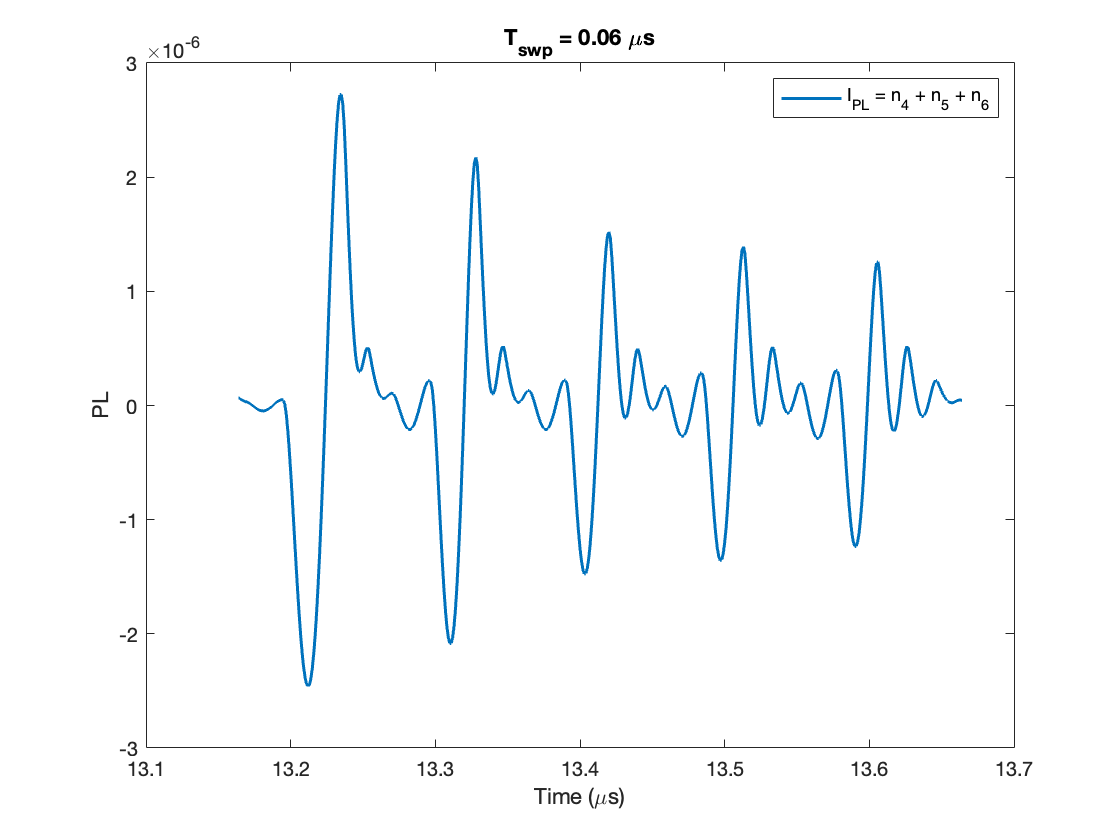

plot(t_2, I_PL, "LineWidth", 1.5);
xlabel('Time (\mus)');
ylabel("PL");
legend("I_{PL} = n_4 + n_5 + n_6")
title("T_{swp} = 0.06 \mus")

### Plot I_PL for the entire sequence

n_res = [n_res_laser_1; n_res_delay_1; n_res_mw; n_res_delay_2; n_res_laser_2; n_res_delay_3];
t = 0 : 1e-3 : T_swp + 13.104;
n_res_4 = n_res(:, 4);
n_res_5 = n_res(:, 5);
n_res_6 = n_res(:, 6);
I_PL = n_res_4 + n_res_5 + n_res_6;

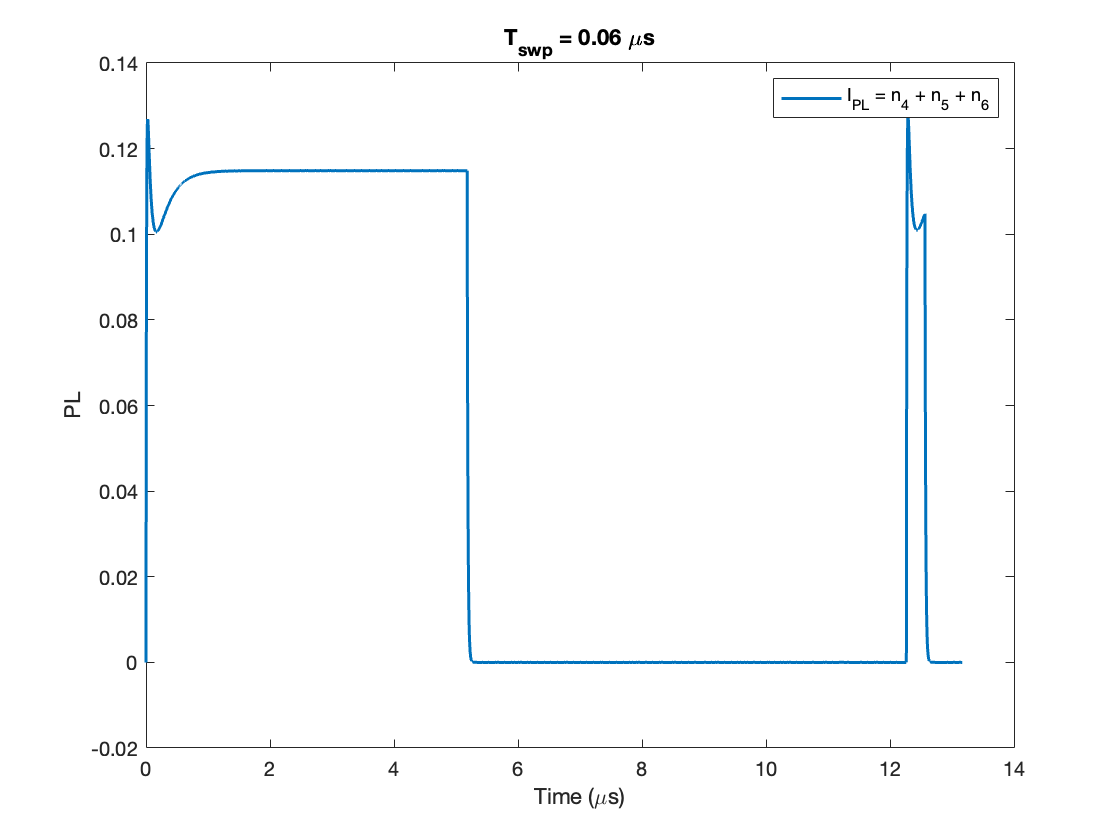

plot(t, I_PL, "LineWidth", 1.5);
xlabel('Time (\mus)');
ylabel("PL");
legend("I_{PL} = n_4 + n_5 + n_6")
title("T_{swp} = 0.06 \mus")

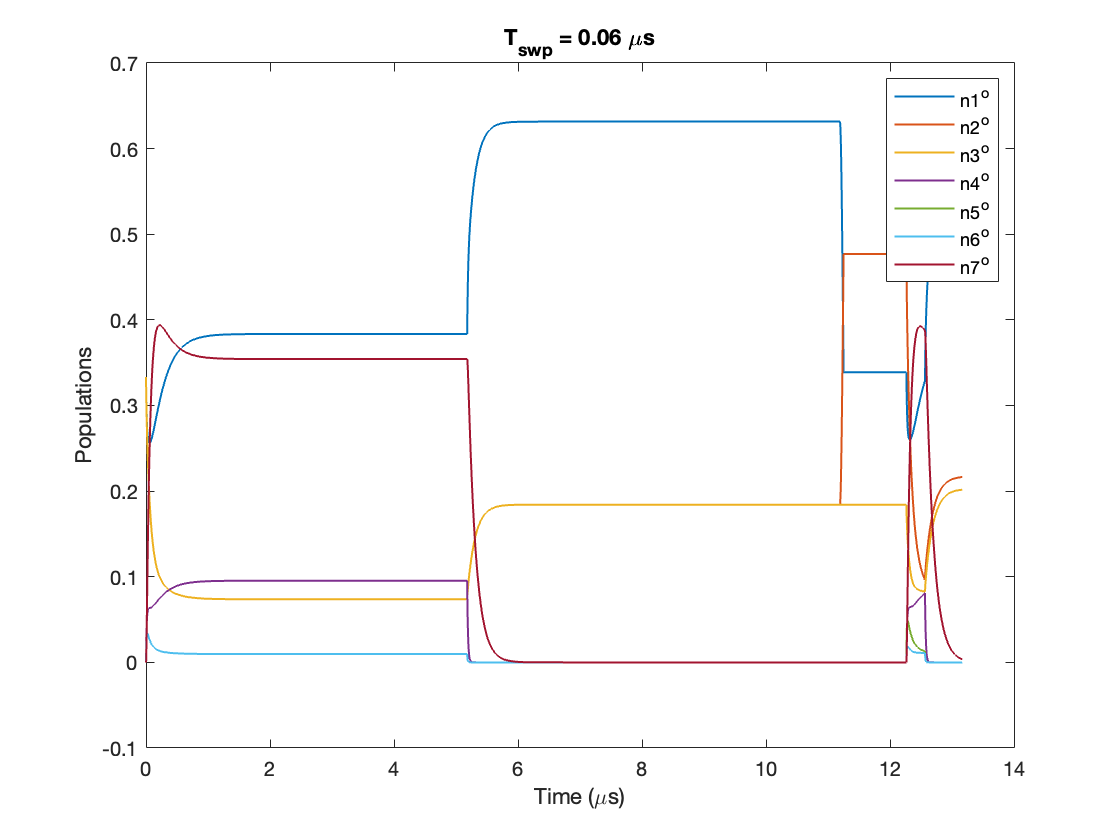

plot(t, n_res, "LineWidth", 1);
xlabel('Time (\mus)');
ylabel("Populations");
legend("n1^o", "n2^o", "n3^o", "n4^o", "n5^o", "n6^o", "n7^o");
title("T_{swp} = 0.06 \mus")

### Calculate the PL signal

t = 12 : 1e-3 : 13

t =    12.0000   12.0010   12.0020   12.0030   12.0040   12.0050   12.0060   12.0070   12.0080   12.0090   12.0100   12.0110   12.0120   12.0130   12.0140   12.0150   12.0160   12.0170   12.0180   12.0190   12.0200   12.0210   12.0220   12.0230   12.0240   12.0250   12.0260   12.0270   12.0280   12.0290   12.0300   12.0310   12.0320   12.0330   12.0340   12.0350   12.0360   12.0370   12.0380   12.0390   12.0400   12.0410   12.0420   12.0430   12.0440   12.0450   12.0460   12.0470   12.0480   12.0490


PL_signal = trapz(t, I_PL(12000 : 13000))

PL_signal = 0.0328

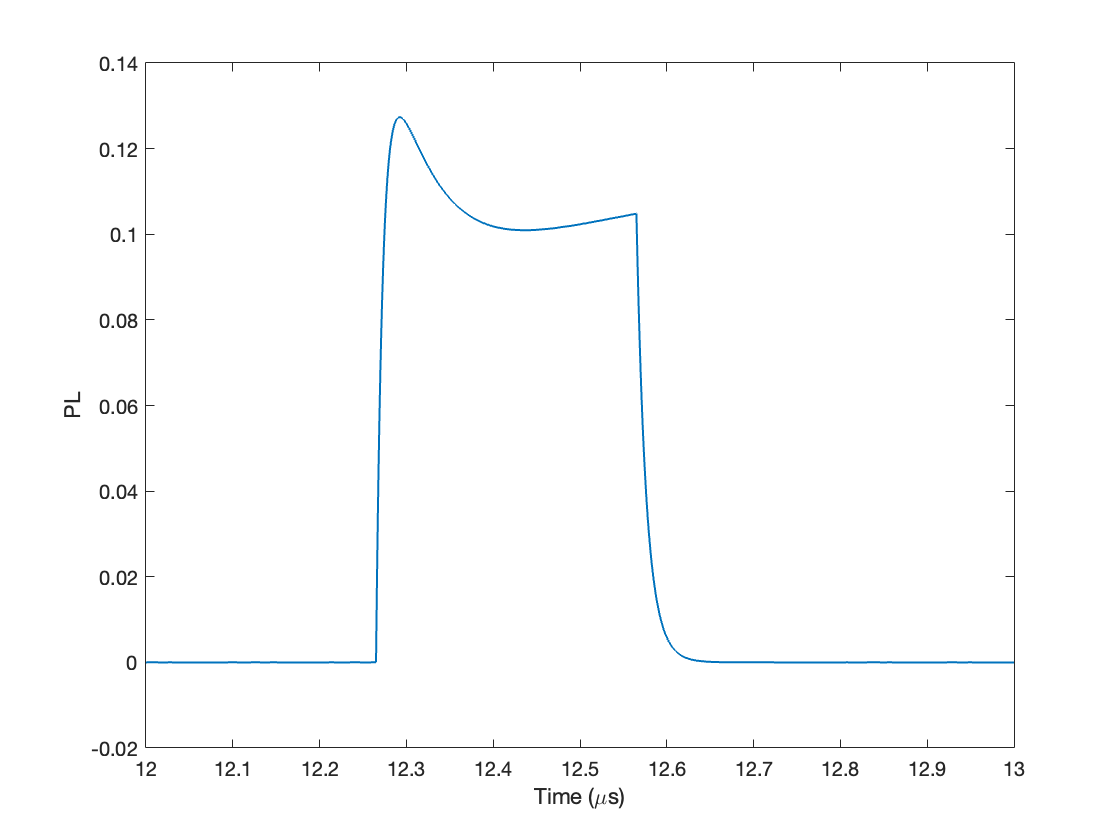

plot(t, I_PL(12000 : 13000), "LineWidth", 1);
xlabel('Time (\mus)');
ylabel("PL");

### PL signal as a function of T_swp